# Creating an Occupancy Grid

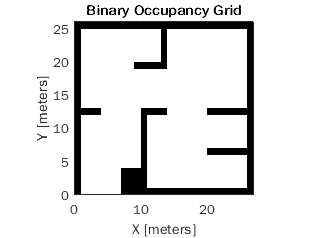

clc
clear all;
load exampleMaps
map = binaryOccupancyMap(simpleMap);
figure
show(map)

% Initializing the robot model and assigning an initial pose
robot = differentialDriveKinematics("TrackWidth", 1, "VehicleInputs", "VehicleSpeedHeadingRate");

## Computing the path using the PRM path planning algorithm

mapInflated = copy(map);
inflate(mapInflated, robot.TrackWidth/2);
%prm = robotics.PRM(mapInflated);
planner=mobileRobotPRM(mapInflated);
planner.NumNodes = 100;
planner.ConnectionDistance = 10;

## Finding a path between the start and end location

startLocation = [4.0 2.0];
endLocation = [20.0 3.0];
path = findpath(planner, startLocation, endLocation)

path =     4.0000    2.0000
    5.3955    2.4816
    5.8447   11.9016
   10.7801   15.5390
   14.7389   14.1178
   15.7256   13.7015
   17.6433    6.5975
   19.8146    2.2742
   20.0000    3.0000


## Displaying the inflated map, the road maps, and the final path.

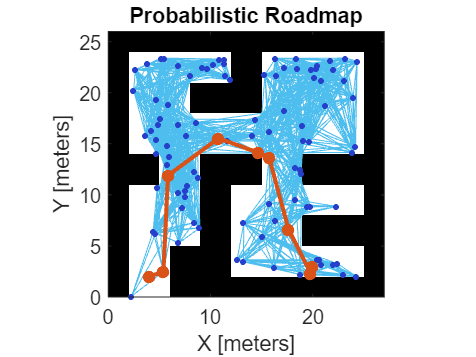

show(planner);

## Defining the Path Following Controller

Creating the path following controller 

controller = controllerPurePursuit;

% Setting the desired waypoints for the controller
controller.Waypoints = path;

% Setting the desired linear velocity is set to 1 meters/second
controller.DesiredLinearVelocity = 1;

% The maximum angular velocity acts as a saturation limit for rotational velocity, which is set at 2 radians/second
controller.MaxAngularVelocity = 2;

controller.LookaheadDistance = 0.3;
% To use the controller and define the waypoints while keeping the other information the same, use the release function.
release(controller);
controller.Waypoints = path;


robot = differentialDriveKinematics("TrackWidth", 1, ...
    "VehicleInputs", "VehicleSpeedHeadingRate");



## Setting initial location and the goal of the robot as defined by the path

robotInitialLocation = path(1,:);
robotGoal = path(end,:);

## Assume an initial robot orientation

initialOrientation = 0;

## Define the current pose for robot motion [x y theta]

robotCurrentPose = [robotInitialLocation initialOrientation]';

## Compute distance to the goal location

distanceToGoal = norm(robotInitialLocation - robotGoal);

## Define a goal radius

goalRadius = 0.1;

## Initialize the simulation loop

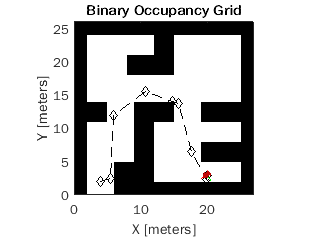

sampleTime = 0.1;
vizRate = rateControl(1/sampleTime);

% Initialize the figure
figure

% Determine vehicle frame size to most closely represent vehicle with plotTransforms
frameSize = robot.TrackWidth/0.8;


% Initialize the figure
figure

while( distanceToGoal > goalRadius )
    
    % Compute the controller outputs, i.e., the inputs to the robot
    [v, omega] = controller(robotCurrentPose);
    
    % Get the robot's velocity using controller inputs
    vel = derivative(robot, robotCurrentPose, [v omega]);
    
    % Update the current pose
    robotCurrentPose = robotCurrentPose + vel*sampleTime; 
    
    % Re-compute the distance to the goal
    distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal(:));
    
    % Update the plot
    hold off
    show(mapInflated);
    hold all

    % Plot path each instance so that it stays persistent while robot mesh
    % moves
    plot(path(:,1), path(:,2),"k--d")
    
    % Plot the path of the robot as a set of transforms
    plotTrVec = [robotCurrentPose(1:2); 0];
    plotRot = axang2quat([0 0 1 robotCurrentPose(3)]);
    plotTransforms(plotTrVec', plotRot, 'MeshFilePath', 'groundvehicle.stl', 'Parent', gca, "View","2D", "FrameSize", frameSize);
    light;
    xlim([0 27])
    ylim([0 26])
    
    waitfor(vizRate);
end